clear

p=10^-12;
n=10^-9;
u=10^-6;
m=10^-3;

R=8;
C=[100*p n 10*n 100*n u 10*u 100*u 1*m];
L=[10*u 100*u m];

rtshigh=zeros(length(C),length(L));
rtslow=zeros(length(C),length(L));

for i=1:length(C)
    for j=1:length(L)
        rtshigh(i,j)=max(abs(roots([1 R/L(j) 1/(L(j)*C(i))])));
        rtslow(i,j)=min(abs(roots([1 R/L(j) 1/(L(j)*C(i))])));
    end
end

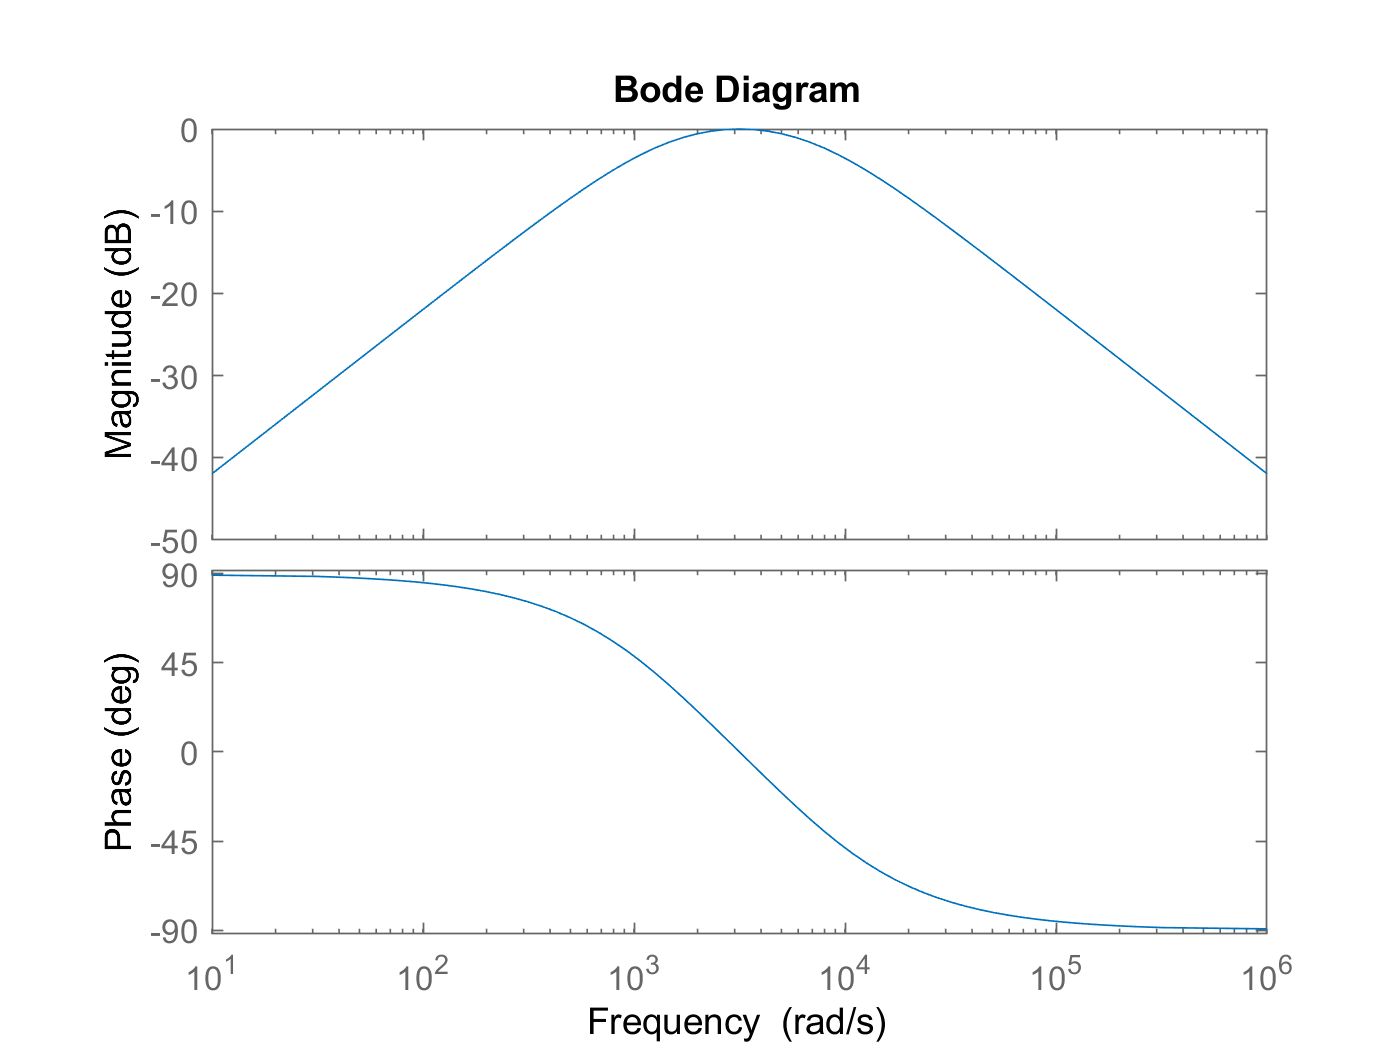

R=8;
L=1*m;
C=100*u;

H=tf([R*C 0],[L*C R*C 1]);
bode(H)


roots([L*C R*C 1])/(2*pi)

ans = 	1.0e+03 *

   -1.0265
   -0.2468


w=482*2*pi;
mag=abs(R*C*w/(-L*C*w^2+j*R*C*w+1))

mag = 0.3296

syms R1 R2 C1 C2 s
G2=1/R2;
G1=1/R1;
matr=[-C2*s G2+C2*s;C2*s+C1*s+G1 -C2*s];
vec=[0;G1];
sol=linsolve(matr,vec);
vo=sol(2);
pretty(collect(vo,s))

                          2
((C2 R2) s)/(C1 C2 R1 R2 s

   + (C1 R1 + C2 R1 + C2 R2) s + 1)



C1=680*u;
C2=100*u;
roots([80*C1*C2 10*C1+18*C2 1])

ans = 	1.0e+03 *

   -1.4545
   -0.1264
